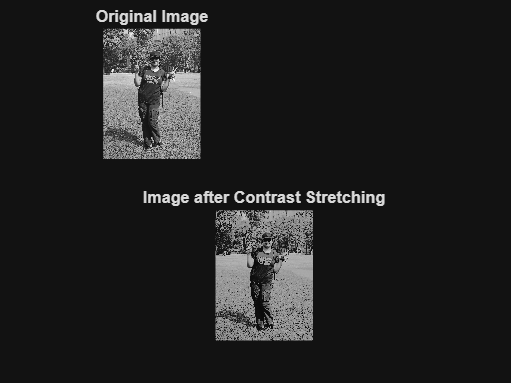

%% Contrast stretching of an image %%
% Slopes taken are 0.5, 2 and 0.5 %
% Read the image (Ensure 'xray1.tif' is in your MATLAB folder)
% If you don't have this specific file, replace with 'pout.tif' or 'cameraman.tif'
a = rgb2gray(imread('DK.jpg'));

% Convert image to double precision for calculations
a = double(a);

% Get image dimensions
[row, col] = size(a);

% Input the threshold values
% Suggested values based on the text: Try LT = 50 and UT = 150
LT = input('Enter the lower threshold value: ');
UT = input('Enter the upper threshold value: ');

% Iterate through every pixel
for x = 1:row
    for y = 1:col
        if a(x,y) < LT
            % Region 1: Compress dark levels (Slope 0.5)
            b(x,y) = 0.5 * a(x,y);
        elseif a(x,y) <= UT
            % Region 2: Stretch middle levels (Slope 2.0)
            % This increases contrast for pixels between LT and UT
            b(x,y) = 2 * (a(x,y) - LT) + 0.5 * LT;
        else
            % Region 3: Compress bright levels (Slope 0.5)
            b(x,y) = 0.5 * (a(x,y) - UT) + 0.5 * LT + 2 * (UT - LT);
        end
    end
end

% Display the results
figure; % Create a new figure window

subplot(2,2,1);
imshow(uint8(a));
title('Original Image');

subplot(2,1,2);
imshow(uint8(b));
title('Image after Contrast Stretching');
exportgraphics(gcf, 'Contrast_Results.png', 'Resolution', 300)